## Lab3.5

(a)

题目要求：题目给出了一个周期离散时间信号的周期与DTFS系数，试问：能否预计x[n]是复数值、纯实数值或是纯虚数值？

分析：由题目给出的系数可知，ak = a-k*，即x[n] = x[n]*，由此可知x[n]是纯实数值。

结论：x[n]是纯实数值。

(b)

题目要求：将DTFS系数储存于向量a中。

分析：a1 = a(-4+5), a3 = a(−2+5). 

clc;
clear;
a = [1 2*exp(-1j*pi/3) exp(1j*pi/4) exp(-1j*pi/4) 2*exp(1j*pi/3)]

a =    1.0000 + 0.0000i   1.0000 - 1.7321i   0.7071 + 0.7071i   0.7071 - 0.7071i   1.0000 + 1.7321i


结论：如上所示。

(c)

题目要求：定义一个向量x，表示x[n]在一个周期内的值，并作出点图，判断（a）中所做的判断是否正确，并注意舍入误差。

x = [zeros(1,5)];
% 用循环给出合成后的x[n]
for n = 1:1:5
    for k = 1:1:5
        x(n) = x(n) + a(k).*exp(1j*(k-1)*2*pi*(n-1)/5);
    end
end
% xq = 5 * ifft(a)
xn = 0:1:4;
% 取出x[n]的实部与虚部，观察数量级差别
x_real = real(x)

x_real =     4.4142    2.9372    3.2001   -3.5622   -1.9894


x_imag = imag(x)

x_imag = 1.0e-14 *

         0   -0.0333   -0.0666    0.1554    0.1332


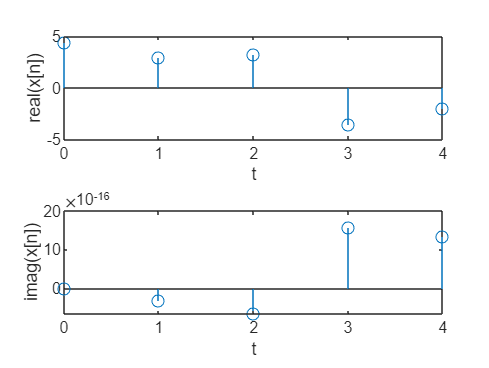

figure
subplot(2,1,1),stem(xn,x_real),ylabel('real(x[n])'),xlabel('t');
subplot(2,1,2),stem(xn,x_imag),ylabel('imag(x[n])'),xlabel('t');

   结论：预测正确，且结果含有微小的舍入误差。

(d)

题目要求：定义三个信号一个周期内的向量表示，利用这三个向量画出0<=n<=63范围内每个信号的图像，并作出适当标注。

x1 = ones(1,8); N1 = 8;
x2 = [ones(1,8) zeros(1,8)]; N2 = 16;
x3 = [ones(1,8) zeros(1,24)]; N3 = 32;
xn = 0:1:63;
x12 = [x1 x1 x1 x1 x1 x1 x1 x1];
x22 = [x2 x2 x2 x2];
x32 = [x3 x3];
figure
subplot(3,1,1),stem(xn,x12),ylabel('x_1[n]'),xlabel('t');
subplot(3,1,2),stem(xn,x22),ylabel('x_2[n]'),xlabel('t');
subplot(3,1,3),stem(xn,x32),ylabel('x_3[n]'),xlabel('t');

结论：如答图。

(e)

题目要求：利用fft计算DTFS系数，并作出序列幅值图，预测三个直流分量，并与函数所得出的结果进行比较。

% 计算DTFS系数
a1 = fft(x1)/N1

a1 =      1     0     0     0     0     0     0     0


a2 = fft(x2)/N2

a2 =    0.5000 + 0.0000i   0.0625 - 0.3142i   0.0000 + 0.0000i   0.0625 - 0.0935i   0.0000 + 0.0000i   0.0625 - 0.0418i   0.0000 + 0.0000i   0.0625 - 0.0124i   0.0000 + 0.0000i   0.0625 + 0.0124i   0.0000 + 0.0000i   0.0625 + 0.0418i   0.0000 + 0.0000i   0.0625 + 0.0935i   0.0000 + 0.0000i   0.0625 + 0.3142i


a3 = fft(x3)/N3

a3 =    0.2500 + 0.0000i   0.1743 - 0.1430i   0.0312 - 0.1571i  -0.0359 - 0.0671i   0.0000 + 0.0000i   0.0449 - 0.0136i   0.0312 - 0.0468i  -0.0034 - 0.0347i   0.0000 + 0.0000i   0.0284 + 0.0028i   0.0312 - 0.0209i   0.0073 - 0.0240i   0.0000 + 0.0000i   0.0204 + 0.0109i   0.0312 - 0.0062i   0.0141 - 0.0172i   0.0000 + 0.0000i   0.0141 + 0.0172i   0.0312 + 0.0062i   0.0204 - 0.0109i   0.0000 + 0.0000i   0.0073 + 0.0240i   0.0312 + 0.0209i   0.0284 - 0.0028i   0.0000 + 0.0000i  -0.0034 + 0.0347i   0.0312 + 0.0468i   0.0449 + 0.0136i   0.0000 + 0.0000i  -0.0359 + 0.0671i   0.0312 + 0.1571i   0.1743 + 0.1430i


预测：a1(1) = 1, a2(1) = 0.5, a3(1) = 0.25.

a1(1)

ans = 1

a2(1)

ans = 0.5000

a3(1)

ans = 0.2500

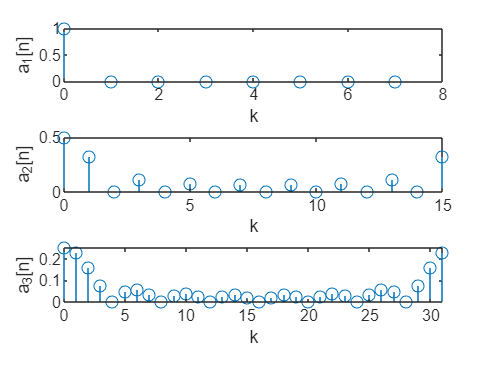

% 绘制图像
subplot(3,1,1),stem(0:7,abs(a1)),ylabel('a_1[n]'),xlabel('k');
subplot(3,1,2),stem(0:15,abs(a2)),ylabel('a_2[n]'),xlabel('k');
subplot(3,1,3),stem(0:31,abs(a3)),ylabel('a_3[n]'),xlabel('k');

结论：与预测相符。

(f)

题目要求：每次用一部分系数来合成信号x[n]，观察合成信号的变化。

% x3_2
a = a3(:,1:3);
a = [conj(flip(a(:,2:3))) a]

a =    0.0312 + 0.1571i   0.1743 + 0.1430i   0.2500 + 0.0000i   0.1743 - 0.1430i   0.0312 - 0.1571i


x3_2 = zeros(1,32);
for n = 1:1:32
    for k = 1:1:5
        x3_2(n) = x3_2(n) + a(k).*exp(1j*(k-3)*2*pi*(n-1)/32);
    end
end
x3_2

x3_2 =    0.6610 + 0.0000i   0.8256 + 0.0000i   0.9478 + 0.0000i   1.0129 + 0.0000i   1.0129 + 0.0000i   0.9478 - 0.0000i   0.8256 + 0.0000i   0.6610 + 0.0000i   0.4735 + 0.0000i   0.2846 + 0.0000i   0.1145 + 0.0000i  -0.0200 + 0.0000i  -0.1084 + 0.0000i  -0.1473 - 0.0000i  -0.1405 + 0.0000i  -0.0985 + 0.0000i  -0.0360 + 0.0000i   0.0303 + 0.0000i   0.0849 + 0.0000i   0.1155 + 0.0000i   0.1155 + 0.0000i   0.0849 + 0.0000i   0.0303 + 0.0000i  -0.0360 + 0.0000i  -0.0985 + 0.0000i  -0.1405 + 0.0000i  -0.1473 + 0.0000i  -0.1084 + 0.0000i  -0.0200 + 0.0000i   0.1145 - 0.0000i   0.2846 + 0.0000i   0.4735 - 0.0000i


% x3_8
a = a3(:,1:9);
a = [conj(flip(a(:,2:9))) a]

a =    0.0000 + 0.0000i  -0.0034 + 0.0347i   0.0312 + 0.0468i   0.0449 + 0.0136i   0.0000 + 0.0000i  -0.0359 + 0.0671i   0.0312 + 0.1571i   0.1743 + 0.1430i   0.2500 + 0.0000i   0.1743 - 0.1430i   0.0312 - 0.1571i  -0.0359 - 0.0671i   0.0000 + 0.0000i   0.0449 - 0.0136i   0.0312 - 0.0468i  -0.0034 - 0.0347i   0.0000 + 0.0000i


x3_8 = zeros(1,32);
for n = 1:1:32
    for k = 1:1:17
        x3_8(n) = x3_8(n) + a(k).*exp(1j*(k-9)*2*pi*(n-1)/32);
    end
end
x3_8

x3_8 =    0.7347 + 0.0000i   1.0900 - 0.0000i   1.0900 + 0.0000i   0.9285 - 0.0000i   0.9285 + 0.0000i   1.0900 - 0.0000i   1.0900 - 0.0000i   0.7347 + 0.0000i   0.2347 + 0.0000i  -0.0570 + 0.0000i  -0.0570 - 0.0000i   0.0293 + 0.0000i   0.0293 + 0.0000i  -0.0197 - 0.0000i  -0.0197 + 0.0000i   0.0153 - 0.0000i   0.0153 + 0.0000i  -0.0134 + 0.0000i  -0.0134 + 0.0000i   0.0128 + 0.0000i   0.0128 + 0.0000i  -0.0134 + 0.0000i  -0.0134 + 0.0000i   0.0153 + 0.0000i   0.0153 + 0.0000i  -0.0197 - 0.0000i  -0.0197 + 0.0000i   0.0293 + 0.0000i   0.0293 - 0.0000i  -0.0570 - 0.0000i  -0.0570 - 0.0000i   0.2347 + 0.0000i


% x3_12
a = a3(:,1:13);
a = [conj(flip(a(:,2:13))) a]

a =    0.0000 + 0.0000i   0.0073 + 0.0240i   0.0312 + 0.0209i   0.0284 - 0.0028i   0.0000 + 0.0000i  -0.0034 + 0.0347i   0.0312 + 0.0468i   0.0449 + 0.0136i   0.0000 + 0.0000i  -0.0359 + 0.0671i   0.0312 + 0.1571i   0.1743 + 0.1430i   0.2500 + 0.0000i   0.1743 - 0.1430i   0.0312 - 0.1571i  -0.0359 - 0.0671i   0.0000 + 0.0000i   0.0449 - 0.0136i   0.0312 - 0.0468i  -0.0034 - 0.0347i   0.0000 + 0.0000i   0.0284 + 0.0028i   0.0312 - 0.0209i   0.0073 - 0.0240i   0.0000 + 0.0000i


x3_12 = zeros(1,32);
for n = 1:1:32
    for k = 1:1:25
        x3_12(n) = x3_12(n) + a(k).*exp(1j*(k-13)*2*pi*(n-1)/32);
    end
end
x3_12

x3_12 =    0.8686 - 0.0000i   1.1199 - 0.0000i   0.9160 + 0.0000i   1.0302 + 0.0000i   1.0302 + 0.0000i   0.9160 - 0.0000i   1.1199 + 0.0000i   0.8686 - 0.0000i   0.1186 + 0.0000i  -0.0876 + 0.0000i   0.0486 + 0.0000i  -0.0124 + 0.0000i  -0.0124 + 0.0000i   0.0222 + 0.0000i  -0.0183 - 0.0000i   0.0064 - 0.0000i   0.0064 - 0.0000i  -0.0139 + 0.0000i   0.0132 + 0.0000i  -0.0053 + 0.0000i  -0.0053 + 0.0000i   0.0132 + 0.0000i  -0.0139 - 0.0000i   0.0064 + 0.0000i   0.0064 - 0.0000i  -0.0183 + 0.0000i   0.0222 + 0.0000i  -0.0124 - 0.0000i  -0.0124 + 0.0000i   0.0486 - 0.0000i  -0.0876 - 0.0000i   0.1186 + 0.0000i


% x3_all
a = a3(:,1:17);
a = [conj(flip(a(:,2:16))) a]

a =    0.0141 + 0.0172i   0.0312 + 0.0062i   0.0204 - 0.0109i   0.0000 + 0.0000i   0.0073 + 0.0240i   0.0312 + 0.0209i   0.0284 - 0.0028i   0.0000 + 0.0000i  -0.0034 + 0.0347i   0.0312 + 0.0468i   0.0449 + 0.0136i   0.0000 + 0.0000i  -0.0359 + 0.0671i   0.0312 + 0.1571i   0.1743 + 0.1430i   0.2500 + 0.0000i   0.1743 - 0.1430i   0.0312 - 0.1571i  -0.0359 - 0.0671i   0.0000 + 0.0000i   0.0449 - 0.0136i   0.0312 - 0.0468i  -0.0034 - 0.0347i   0.0000 + 0.0000i   0.0284 + 0.0028i   0.0312 - 0.0209i   0.0073 - 0.0240i   0.0000 + 0.0000i   0.0204 + 0.0109i   0.0312 - 0.0062i   0.0141 - 0.0172i   0.0000 + 0.0000i


x3_all = zeros(1,32);
for n = 1:1:32
    for k = 1:1:32
        x3_all(n) = x3_all(n) + a(k).*exp(1j*(k-16)*2*pi*(n-1)/32);
    end
end
x3_all

x3_all =    1.0000 - 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i


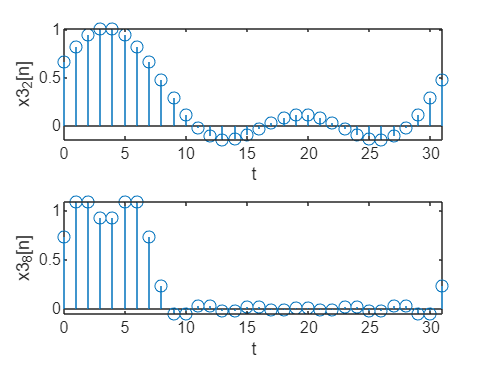

figure
subplot(2,1,1),stem(0:31,real(x3_2)),ylabel('x3_2[n]'),xlabel('t');
subplot(2,1,2),stem(0:31,real(x3_8)),ylabel('x3_8[n]'),xlabel('t');

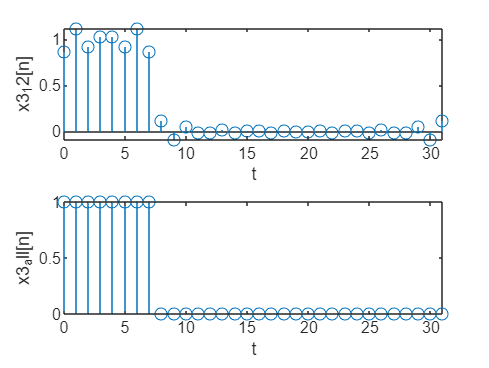

figure
subplot(2,1,1),stem(0:31,real(x3_12)),ylabel('x3_12[n]'),xlabel('t');
subplot(2,1,2),stem(0:31,real(x3_all)),ylabel('x3_all[n]'),xlabel('t')

结论：如答图。

(g)

题目要求：论证x3_all一定是实信号。

imag(x3_all)

ans = 1.0e-16 *

   -0.5898   -0.0694    0.1041   -0.1388    0.0347    0.0694    0.2082    0.4857   -0.0867    0.0694    0.0954         0   -0.1735    0.0173   -0.0347   -0.0173   -0.1041   -0.0347         0         0         0   -0.0347    0.0694         0    0.0694    0.0694   -0.0347    0.0694    0.1041    0.1388    0.2255   -0.2429


分析：我们可以看到虚部的数量级非常小；除此之外，由ak = a-k*，令

则经推导知，f(k) + f(-k) = f(k) + f(-k)*，可知f(k) + f(-k)为实数，又有f(0) = a_0为实数，f(N/2) = a_(N-1)为实数，则其累加和x3_all[n]一定为实信号。

(h)

题目要求：用图像展现随着更多DTFS系数被包括在和式之中，信号是如何逐渐收敛到x3[n]的，这个方波是否展现出吉布斯现象？

% x3_4
a = a3(:,1:5);
a = [conj(flip(a(:,2:5))) a]

a =    0.0000 + 0.0000i  -0.0359 + 0.0671i   0.0312 + 0.1571i   0.1743 + 0.1430i   0.2500 + 0.0000i   0.1743 - 0.1430i   0.0312 - 0.1571i  -0.0359 - 0.0671i   0.0000 + 0.0000i


x3_4 = zeros(1,32);
for n = 1:1:32
    for k = 1:1:9
        x3_4(n) = x3_4(n) + a(k).*exp(1j*(k-5)*2*pi*(n-1)/32);
    end
end
x3_4

x3_4 =    0.5893 + 0.0000i   0.8405 + 0.0000i   1.0444 - 0.0000i   1.1586 + 0.0000i   1.1586 + 0.0000i   1.0444 + 0.0000i   0.8405 + 0.0000i   0.5893 + 0.0000i   0.3393 - 0.0000i   0.1330 - 0.0000i  -0.0032 + 0.0000i  -0.0642 - 0.0000i  -0.0642 + 0.0000i  -0.0296 - 0.0000i   0.0110 + 0.0000i   0.0357 + 0.0000i   0.0357 + 0.0000i   0.0154 + 0.0000i  -0.0117 + 0.0000i  -0.0302 + 0.0000i  -0.0302 + 0.0000i  -0.0117 + 0.0000i   0.0154 + 0.0000i   0.0357 + 0.0000i   0.0357 + 0.0000i   0.0110 + 0.0000i  -0.0296 + 0.0000i  -0.0642 + 0.0000i  -0.0642 + 0.0000i  -0.0032 - 0.0000i   0.1330 + 0.0000i   0.3393 + 0.0000i


% x3_6
a = a3(:,1:7);
a = [conj(flip(a(:,2:7))) a]

a =    0.0312 + 0.0468i   0.0449 + 0.0136i   0.0000 + 0.0000i  -0.0359 + 0.0671i   0.0312 + 0.1571i   0.1743 + 0.1430i   0.2500 + 0.0000i   0.1743 - 0.1430i   0.0312 - 0.1571i  -0.0359 - 0.0671i   0.0000 + 0.0000i   0.0449 - 0.0136i   0.0312 - 0.0468i


x3_6 = zeros(1,32);
for n = 1:1:32
    for k = 1:1:13
        x3_6(n) = x3_6(n) + a(k).*exp(1j*(k-7)*2*pi*(n-1)/32);
    end
end
x3_6

x3_6 =    0.7415 + 0.0000i   1.0234 - 0.0000i   1.0572 + 0.0000i   0.9824 + 0.0000i   0.9824 + 0.0000i   1.0572 + 0.0000i   1.0234 - 0.0000i   0.7415 - 0.0000i   0.3040 + 0.0000i  -0.0368 + 0.0000i  -0.1184 + 0.0000i  -0.0149 - 0.0000i   0.0735 + 0.0000i   0.0418 - 0.0000i  -0.0399 + 0.0000i  -0.0540 - 0.0000i   0.0085 - 0.0000i   0.0533 + 0.0000i   0.0195 + 0.0000i  -0.0410 + 0.0000i  -0.0410 + 0.0000i   0.0195 - 0.0000i   0.0533 + 0.0000i   0.0085 + 0.0000i  -0.0540 + 0.0000i  -0.0399 + 0.0000i   0.0418 + 0.0000i   0.0735 + 0.0000i  -0.0149 - 0.0000i  -0.1184 - 0.0000i  -0.0368 + 0.0000i   0.3040 - 0.0000i


% x3_10
a = a3(:,1:11);
a = [conj(flip(a(:,2:11))) a]

a =    0.0312 + 0.0209i   0.0284 - 0.0028i   0.0000 + 0.0000i  -0.0034 + 0.0347i   0.0312 + 0.0468i   0.0449 + 0.0136i   0.0000 + 0.0000i  -0.0359 + 0.0671i   0.0312 + 0.1571i   0.1743 + 0.1430i   0.2500 + 0.0000i   0.1743 - 0.1430i   0.0312 - 0.1571i  -0.0359 - 0.0671i   0.0000 + 0.0000i   0.0449 - 0.0136i   0.0312 - 0.0468i  -0.0034 - 0.0347i   0.0000 + 0.0000i   0.0284 + 0.0028i   0.0312 - 0.0209i


x3_10 = zeros(1,32);
for n = 1:1:32
    for k = 1:1:21
        x3_10(n) = x3_10(n) + a(k).*exp(1j*(k-11)*2*pi*(n-1)/32);
    end
end
x3_10

x3_10 =    0.8541 - 0.0000i   1.0881 - 0.0000i   0.9659 + 0.0000i   1.0066 + 0.0000i   1.0066 + 0.0000i   0.9659 + 0.0000i   1.0881 - 0.0000i   0.8541 + 0.0000i   0.1666 + 0.0000i  -0.1264 - 0.0000i   0.0437 - 0.0000i   0.0318 - 0.0000i  -0.0566 + 0.0000i   0.0271 + 0.0000i   0.0204 + 0.0000i  -0.0416 + 0.0000i   0.0209 - 0.0000i   0.0179 - 0.0000i  -0.0367 + 0.0000i   0.0183 + 0.0000i   0.0183 - 0.0000i  -0.0367 + 0.0000i   0.0179 + 0.0000i   0.0209 + 0.0000i  -0.0416 + 0.0000i   0.0204 + 0.0000i   0.0271 + 0.0000i  -0.0566 + 0.0000i   0.0318 - 0.0000i   0.0437 - 0.0000i  -0.1264 + 0.0000i   0.1666 - 0.0000i


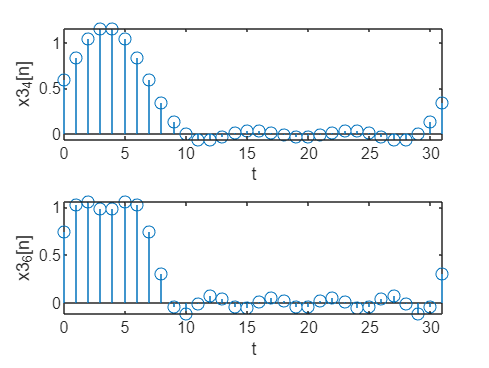


figure
subplot(2,1,1),stem(0:31,real(x3_4)),ylabel('x3_4[n]'),xlabel('t');
subplot(2,1,2),stem(0:31,real(x3_6)),ylabel('x3_6[n]'),xlabel('t');

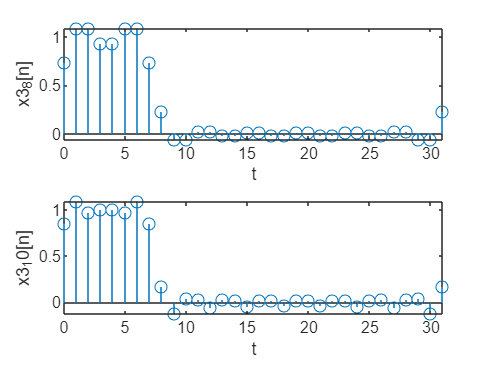

figure
subplot(2,1,1),stem(0:31,real(x3_8)),ylabel('x3_8[n]'),xlabel('t');
subplot(2,1,2),stem(0:31,real(x3_10)),ylabel('x3_10[n]'),xlabel('t');

figure
subplot(2,1,1),stem(0:31,real(x3_12)),ylabel('x3_12[n]'),xlabel('t');
subplot(2,1,2),stem(0:31,real(x3_all)),ylabel('x3_all[n]'),xlabel('t')

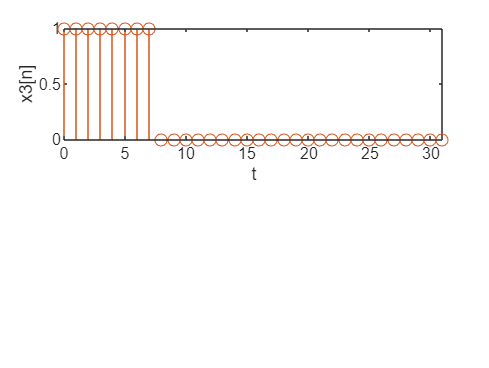


figure
subplot(2,1,1),stem(0:31,real(x3_all)),ylabel('x3_12[n]'),xlabel('t');
hold on
subplot(2,1,1),stem(0:31,real(x3)),ylabel('x3[n]'),xlabel('t')
hold off


% 如图所示x3_all[n]与x3[n]是相等的


结论：如答图显示，信号逐渐收敛到x3_all[n] = x3[n]，没有展现吉布斯现象。

(i)

题目要求：写出一个计算周期信号DTFS系数的函数。

% 函数文件另附m文件中
dtfs([1 2 3 4], 0)

ans =    2.5000 + 0.0000i  -0.5000 + 0.5000i  -0.5000 + 0.0000i  -0.5000 - 0.5000i


dtfs([1 2 3 4], 1)

ans =    2.5000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.0000i   0.5000 - 0.5000i


dtfs([1 2 3 4], -1)

ans =    2.5000 + 0.0000i  -0.5000 - 0.5000i   0.5000 + 0.0000i  -0.5000 + 0.5000i


dtfs([2 3 4 1], 0)

ans =    2.5000 + 0.0000i  -0.5000 - 0.5000i   0.5000 + 0.0000i  -0.5000 + 0.5000i


dtfs([ones(1,4) zeros(1,4)], 0)

ans =    0.5000 + 0.0000i   0.1250 - 0.3018i   0.0000 + 0.0000i   0.1250 - 0.0518i   0.0000 + 0.0000i   0.1250 + 0.0518i   0.0000 + 0.0000i   0.1250 + 0.3018i


dtfs([ones(1,4) zeros(1,4)], 2)

ans =    0.5000 + 0.0000i  -0.3018 - 0.1250i   0.0000 + 0.0000i   0.0518 + 0.1250i   0.0000 + 0.0000i   0.0518 - 0.1250i   0.0000 + 0.0000i  -0.3018 + 0.1250i


结论：测试结果如运行结果所示，输出一致。